# Problem 1

clear; clc ; close all;

syms t   

f = 3;
y = cos(2*pi*f*t);

% (b) 3Hz Cosine wave with high sampling rate (assumed to be analog)
ncycle = 4/f;
Fsa = 10000; 
ta = 0:1/Fsa:ncycle;
ya = subs(y, t, ta);

fig1 = figure(1);
set(fig1,'Position', [100 100 1100 700]);

subplot(311); plot(ta,ya,'-b', 'linewidth', 2);hold on;
legend('Analog'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)');
title('3 Hz Cosine Wave - High Sampling Rate');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold');

% (c) 3 Hz cosine wave sampling with 10 Hz
Fsd = 10; 
td = 0:1/Fsd:ncycle;
yd = subs(y, t, td);

subplot(312); plot(td,yd,'or','linewidth',2); 
legend('digital'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)');
title('3 Hz Cosine Wave - Sampling Rate 10 Hz');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

% (d) 6Hz sine wave sampling with 12 Hz
f2 = 6;
y2 = sin(2*pi*f2*t);

ncycle = 4/f;
Fsa = 10000; 
ta2 = 0:1/Fsa:ncycle;
ya2 = subs(y2, t, ta2);


Fsd2 = 12; 
td2 = 0:1/Fsd2:ncycle;
yd2 = subs(y2, t, td2);

subplot(313); plot(td2,yd2,'or','linewidth',2); 
legend('digital'); axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)');
title('6 Hz Sine Wave - Sampling Rate 12 Hz');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

# Problem 2

clear; clc ; close all;

syms t   

% (a) 10 Hz sine wave sampled at 12 Hz

f = 10;
y = sin(2*pi*f*t);

ncycle = 2;
Fsa = 1000; 
ta = 0:1/Fsa:ncycle;
ya = subs(y, t, ta); 

Fsd1 = 12; 
td1 = 0:1/Fsd1:ncycle;
yd1 = subs(y, t, td1);

alias_freq1 = Fsd1/2;

subplot(211); plot(ta,ya,':k', 'linewidth', 1); hold on;
plot(td1,yd1,'ob','linewidth',2); 
plot(td1,yd1,':b','linewidth',1); hold off;
legend('Analog', 'digital sampling'); grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)'); 
title('10 Hz Sine Wave - Sampling Rate 12 Hz');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')


% (b) 12 Hz cosine wave sampled at 12 Hz

f2 = 12;
y2 = cos(2*pi*f2*t);

ncycle = 2;
Fsa = 1000;
ta2 = 0:1/Fsa:ncycle;
ya2 = subs(y2, t, ta2); 

Fsd2 = 12; 
td2 = 0:1/Fsd2:ncycle;
yd2 = subs(y2, t, td2);

alias_freq2 = Fsd2/2;

subplot(212); plot(ta2,ya2,':b', 'linewidth', 1); hold on;
plot(td2,yd2,'om','linewidth',2); 
plot(td2,yd2,':m','linewidth',1); hold off;
legend('Analog', 'digital sampling');
axis tight;grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)');
title('12 Hz Cosine Wave - Sampling Rate 12 Hz');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

clear; clc ; close all;

syms t   

% (c)
% The frequency content of the resulting discrete response signal is 25.

f1 = 25;
f2 = 75;
f3 = 125;
y = sin(2*pi*f1*t)+sin(2*pi*f2*t)+sin(2*pi*f3*t);

ncycle = 0.1;
Fsa = 1000;
ta = 0:1/Fsa:ncycle;
ya = subs(y, t, ta); 


Fsd1 = 100; 
td1 = 0:1/Fsd1:ncycle;
yd1 = subs(y, t, td1);

plot(ta,ya,':k', 'linewidth', 1); hold on;
plot(td1,yd1,'ob','linewidth',2); 
plot(td1,yd1,':b','linewidth',1); hold off;
legend('Analog', 'digital sampling'); grid on;
ylabel('\bf Amplitude'); ylim([-1.3 1.3]);
xlabel('\bf Time (sec)'); 
title('y(t) - Sampling Rate 100 Hz');
set(gca,'fontsize',15,'linewidth',2,'fontweight','bold')

# Problem 3

% (d)

clear; clc ; close all;

syms t   

f = 10;
y = sin(2*pi*f*t);
ncycle = 2;
Fsa = 1000;
ta = 0:1/Fsa:ncycle;
ya = subs(y, t, ta);

% Aliasing
% Happens when Nyquist frequency is smaller than the frequency of the wave.

Fsd1 = 12; % # of samples per a second
td1 = 0:1/Fsd1:ncycle;
yd1 = subs(y, t, td1);

subplot(411); 
plot(ta,ya,':k'); hold on;
plot(td1,yd1,'ob', td1, yd1, ':b'); hold off;
grid on;
ylabel('Amplitude'); ylim([-1.3 1.3]);
xlabel('Time (sec)'); 
title('Aliasing Error');

% Quantization
% Happens when trying to transform analog signal to digital signal


f1 = 1;
y1 = sin(2*pi*f1*t);
ya1 = subs(y1, t, ta);

yd2 = subs(y1, t, td1);

resol = 1/4;
yd2_digit = interp1(-10:resol:10, -10:resol:10, double(yd2), 'nearest');

subplot(412);
plot(td1,yd2,':r'); hold on;
plot(td1,yd2_digit, ':b',td1, yd2_digit, 'ob'); hold off;
grid on;
ylabel('Amplitude'); ylim([-1.3 1.3]);
xlabel('Time (sec)');
title('Quantization');

% Clipping
% Happens when a signal has constraints on the range of data it can measure [(-0.5 0.5)] in this case
resol2 = 1/4;
yd3_digit = interp1(-0.5:resol2:0.5, -0.5:resol2:0.5, double(ya), 'nearest', 'extrap');

subplot(413);
plot(ta,ya,':r', 'linewidth', 1); hold on;
plot(ta, yd3_digit, ':b', ta, yd3_digit, 'ob', 'MarkerSize', 1); hold off;
grid on;
ylabel('Amplitude'); ylim([-1.3 1.3]);
xlabel('Time (sec)');
title('Clipping');

% Oversampling
% Happens when sampling frequency significantly higher than the Nyquist rate
Fsd3 = 300;
td3 = 0:1/Fsd3:ncycle;
yd3 = subs(y, t, td3);

subplot(414);
plot(ta,ya,':r'); hold on;
plot(td3,yd3,'ob','MarkerSize',2); hold off;
grid on;
ylabel('Amplitude'); ylim([-1.3 1.3]);
xlabel('Time (sec)');
title('Oversampling')

# Problem 4

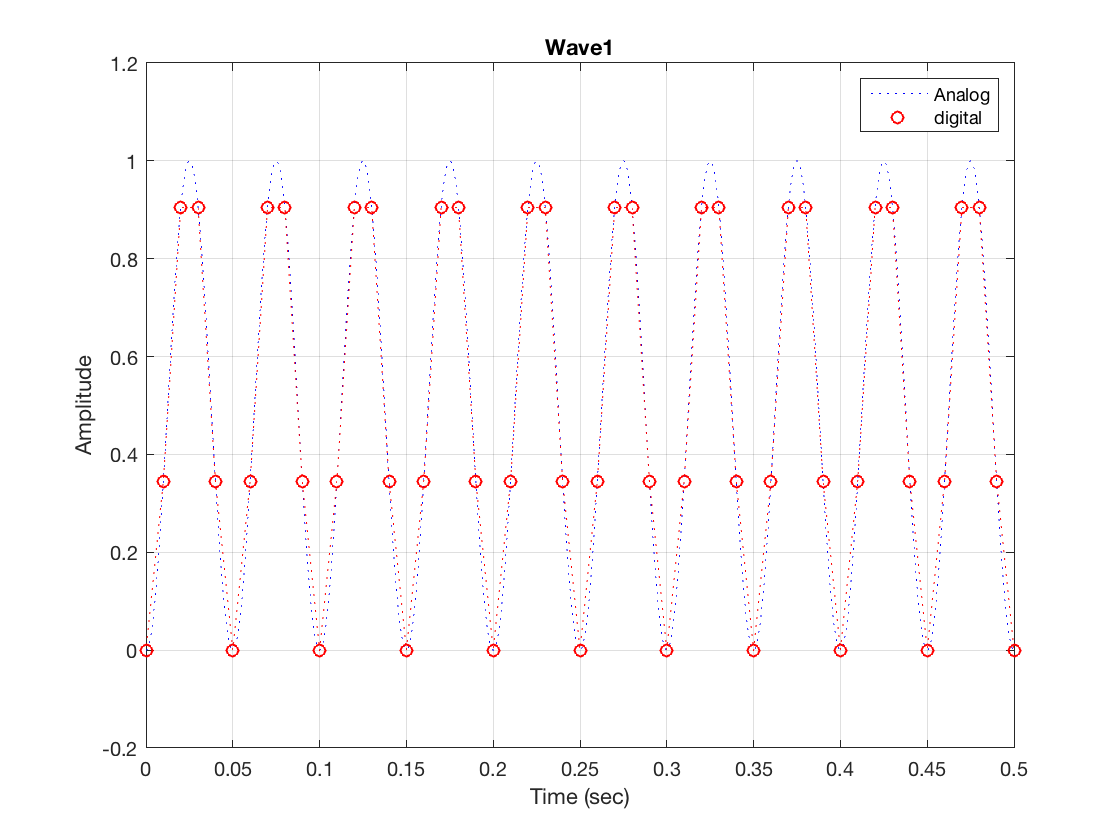

clear; clc ; close all;

syms t   

% (a) Plot of Wave1

f = 10;
y = sin(2*pi*f*t)*sin(2*pi*f*t);

ncyle = 10/f;
Fsa = 10000; 
ta = 0:1/Fsa:ncyle;
ya = subs(y, t, ta);

Fsd = 100; 
td = 0:1/Fsd:ncyle;
yd = subs(y, t, td);

plot(ta,ya,':b'); hold on;
plot(td,yd,'or',td,yd,':r'); hold off;
legend('Analog', 'digital'); axis tight;grid on;
ylabel('Amplitude'); ylim([-0.2 1.2]);
xlabel('Time (sec)'); xlim([0 0.5]);
title('Wave1')

# Problem 5

clear; clc ; close all;

syms t   

% (a)

y = t-floor(t);

ncycle = 10;
Fsa = 1000; 
ta = 0:1/Fsa:ncycle;
ya = subs(y, t, ta);

plot(ta,ya,':b');
grid on;
ylabel('Amplitude'); ylim([-0.3 1.3]);
xlabel('Time (sec)'); 
title('Sawtooth Wave')

% (d) Plot to approximate sawtooth wave

tp = 1; 

% General form
n = 8;
sum = 0;
for i = 1:n;
    sum = sum+(-1/(pi*i)*sin(2*pi*i*ta)+0.5);
end
plot(ta,sum); grid on;
xlabel('Time (sec)');
ylabel('Amplitude');
title('Sawtooth Wave Fourier Series General Form')

% Complex form
sum1 = 0;
for j = 1:n;
    sum1 = sum1 - (1/(1i*2*pi*j)*(exp(1).^(1i*2*pi*j*ta)));
end
plot(ta,real(sum1)); grid on;
xlabel('Time (sec)');
ylabel('Amplitude');
title('Sawtooth Wave Fourier Series Complex Form')

% The waves for general form and complex form are approximately the same in shape and match the plot of the original wave.

% (e) Numerical Fourier coefficients

% General form
bn_fun=@(t) (t-floor(t)).*sin(2*pi.*t/tp);
bn = 2/tp*integral(bn_fun, -tp/2, tp/2)
a0_fun=@(t) t-floor(t);
a0 = 2*1/tp*integral(a0_fun, -tp/2, tp/2)
an_fun=@(t) (t-floor(t)).*cos(2*pi.*t/tp);
an = 2/tp*integral(an_fun, -tp/2, tp/2)

% Complex form

cn_fun=@(t) (t-floor(t)).*exp(1).^(-1i*(2*pi/tp).*t);
cn = 1/tp*integral(cn_fun, 0, tp)

% The results are approximately the same. a0 and bn are the same and an is only slightly greater than 0.

# Problem 7

clear; clc ; close all;

% (b)

a1=1;
b=2;
c=6;
f1=3;
f2=6;

% Plot in time domain
y1 = @(t) (exp(1).^(-a1*abs(t))).*(b*cos(2*pi*f1*t)+c*cos(2*pi*f2*t));

fplot(y1); grid on;
xlabel('Time (sec)');
ylabel('Amplitude');
title('First set: Time domain')

% Plot in frequency domain

yf1 = @(f) a1*b./(a1^2+(2*pi.*(f-f1)).^2)+...
    a1*b./(a1^2+(2*pi.*(f+f1)).^2)+...
    a1*c./(a1^2+(2*pi.*(f-f2)).^2)+...
    a1*c./(a1^2+(2*pi.*(f+f2)).^2);

fplot(yf1); grid on;
xlabel('Time (sec)'); xlim([-8 8]);
ylabel('Amplitude'); ylim([0 6]);
title('First set: Frequency domain')

% (c)

a2=0.5;

% Plot in time domain

y2 = @(t) (exp(1).^(-a2*abs(t))).*(b*cos(2*pi*f1.*t)+c*cos(2*pi*f2.*t));

fplot(y2); grid on;
xlabel('Time (sec)');
ylabel('Amplitude');
title('Second set: Time domain')

% Plot in frequency domain

yf2 = @(f) a2*b./(a2^2+(2*pi.*(f-f1)).^2)+...
    a2*b./(a2^2+(2*pi.*(f+f1)).^2)+...
    a2*c./(a2^2+(2*pi.*(f-f2)).^2)+...
    a2*c./(a2^2+(2*pi.*(f+f2)).^2);

fplot(yf2); grid on;
xlabel('Time (sec)'); xlim([-8 8]);
ylabel('Amplitude'); ylim([0 13]);
title('Second set: Frequency domain')
